# Quizz Understanding the Flights Dataset

flightsJan = importFlightsData("flightsJan.csv")

flightsJan = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    _________


sort(flightsJan.ACTUAL_ELAPSED_TIME)

ans =     17
    17
    17
    17
    17
    18
    18
    18
    19
    19


corr(flightsJan.ARRIVAL_DELAY, flightsJan.DEPARTURE_DELAY,"rows","complete")

ans = 0.9381


corr(flightsJan.ARRIVAL_DELAY, flightsJan.TAXI_OUT,"rows","complete")

ans = 0.2490


corr(flightsJan.ARRIVAL_DELAY, flightsJan.TAXI_IN,"rows","complete")

ans = 0.1605


corr(flightsJan.ARRIVAL_DELAY, flightsJan.SCHEDULED_ELAPSED_TIME,"rows","complete")

ans = -0.0467

groupsummary(flightsJan,"CANCELLATION_CODE")

ans = 5×2 table
    CANCELLATION_CODE    GroupCount
    _________________    __________

       A                       2874
       B                       7020
       C                       2087
       D                          1
       <undefined>       4.5799e+05


flightsAug = importFlightsData("flightsAug.csv")

flightsAug = 510536×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    _________

groupsummary(flightsAug,"CANCELLATION_CODE")

ans = 5×2 table
    CANCELLATION_CODE    GroupCount
    _________________    __________

       A                       2364
       B                       1310
       C                       1376
       D                          2
       <undefined>       5.0548e+05


# Module 1 Quiz

flightsJan = importFlightsData("flightsJan.csv")

flightsJan = 469968×20 table
         AIRLINE         TAIL_NUMBER    FLIGHT_NUMBER    ORIGIN    DESTINATION    SCHEDULED_DEPARTURE_TIME    ACTUAL_DEPARTURE_TIME    DEPARTURE_DELAY    TAXI_OUT    AIR_TIME    TAXI_IN    SCHEDULED_ARRIVAL_TIME    ACTUAL_ARRIVAL_TIME     ARRIVAL_DELAY    SCHEDULED_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    DISTANCE    CANCELLED    CANCELLATION_CODE    DIVERTED
    _________________    ___________    _____________    ______    ___________    ________________________    _____________________    _________


groupsummary(flightsJan,"ORIGIN");
sortrows(ans,'GroupCount','descend')

ans = 312×2 table
    ORIGIN    GroupCount
    ______    __________

     ATL        29512   
     ORD        23484   
     DFW        23153   
     LAX        17340   
     DEN        17090   
     IAH        13376   
     PHX        13122   
     SFO        12891   
     LAS        11604   
     MCO        10083   
     LGA         9517   
     DTW         9473   
     CLT         9350   
     MSP         8903   
     BOS         8837   
     EWR         8697   



groupsummary(flightsJan,"ORIGIN","mean","DISTANCE");
sortrows(ans,'mean_DISTANCE','ascend')

ans = 312×3 table
    ORIGIN    GroupCount    mean_DISTANCE
    ______    __________    _____________

     WRG          62             56.5    
     PSG          62               77    
     CSG          80               83    
     CLD         204               86    
     ACT         147               89    
     PUB          53              109    
     LAR          62              113    
     SPS         106              113    
     TYR         193           115.27    
     BRD          54           115.44    
     MKG          62              118    
     FLG         142              119    
     SIT          92           124.65    
     VEL          53              132    
     SMX          60              134    
     GGG          54              140    



sum(flightsJan.CANCELLED)

ans = 11982

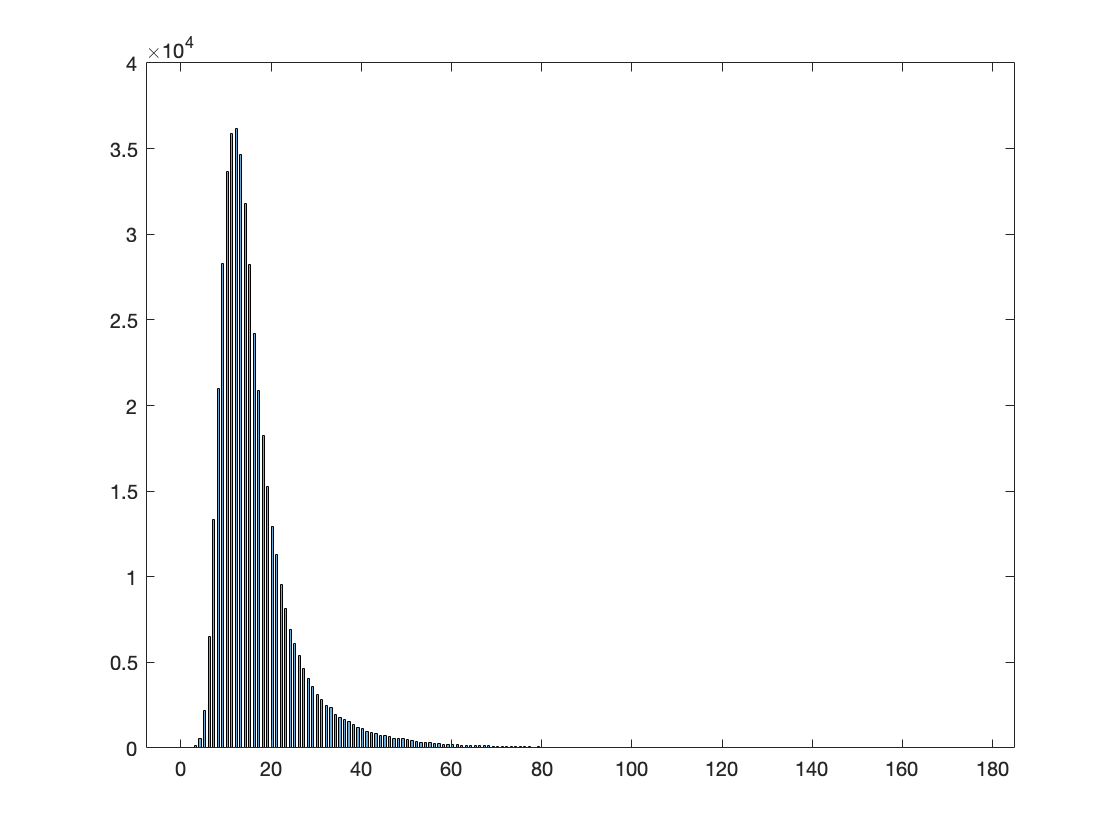

histogram(flightsJan.TAXI_OUT)